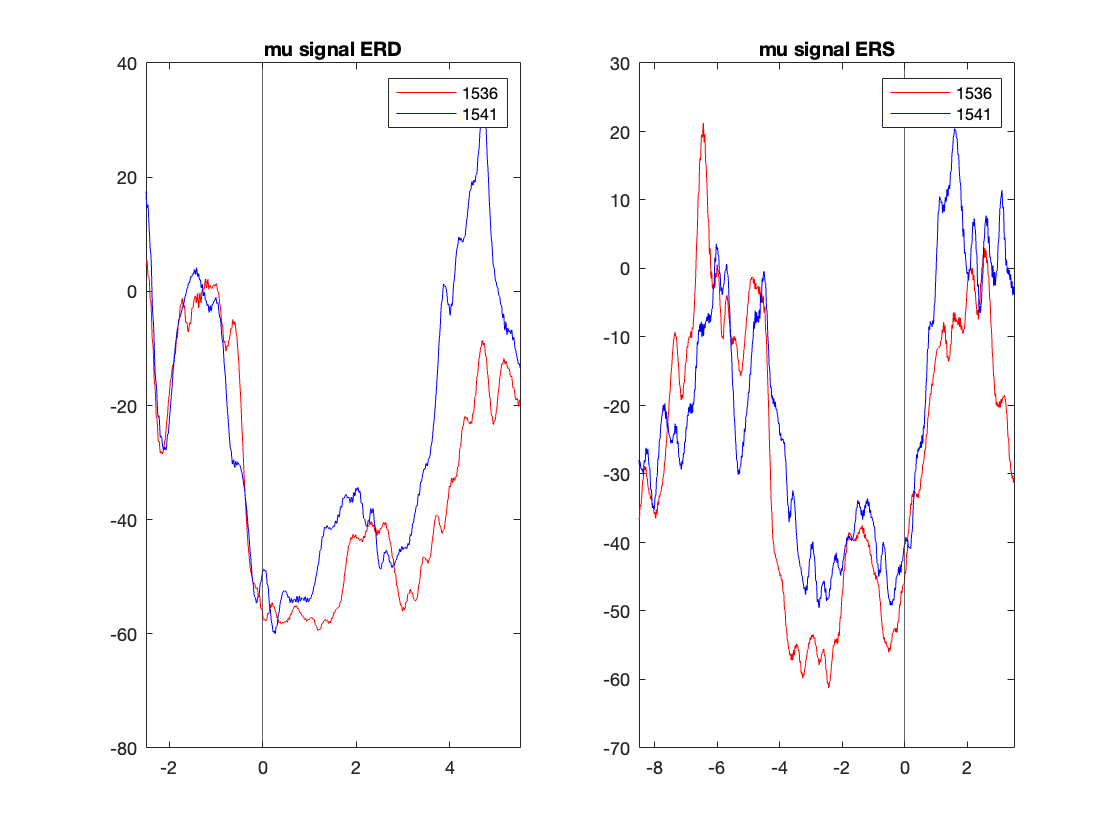

 %[grand_mean_mu_1541,grand_mean_beta_1541,ERD_mu_1541,ERD_beta_1541,grand_mean_mu_ERP_1541,grand_mean_beta_ERP_1541,ERP_mu_1541,ERP_beta_1541] = D6_function(1541,[false,true],subject_list,data,icadata, true);
 %[grand_mean_mu_1536,grand_mean_beta_1536,ERD_mu_1536,ERD_beta_1536,grand_mean_mu_ERP_1536,grand_mean_beta_ERP_1536,ERP_mu_1536,ERP_beta_1536] = D6_function(1536,[false,true],subject_list,data,icadata, true);
% 

t=-2.5+1/512:1/512:5.5;
t_ERP = -8.5+1/512:1/512:3.5;

figure();
%set(G1,'Position',[10 10 2000 750]);
subplot(1,2,1)
plot(t,grand_mean_mu_1536(43,:),'red')
hold on 
plot(t,grand_mean_mu_1541(43,:),'blue')
xline(0);xlim([-2.5 5.5]);legend('1536','1541');title('mu signal ERD')

subplot(1,2,2)
plot(t_ERP,grand_mean_mu_ERP_1536(43,:),'red')
hold on 
plot(t_ERP,grand_mean_mu_ERP_1541(43,:),'blue')
xline(0);xlim([-8.5 3.5]);legend('1536','1541');title('mu signal ERS')

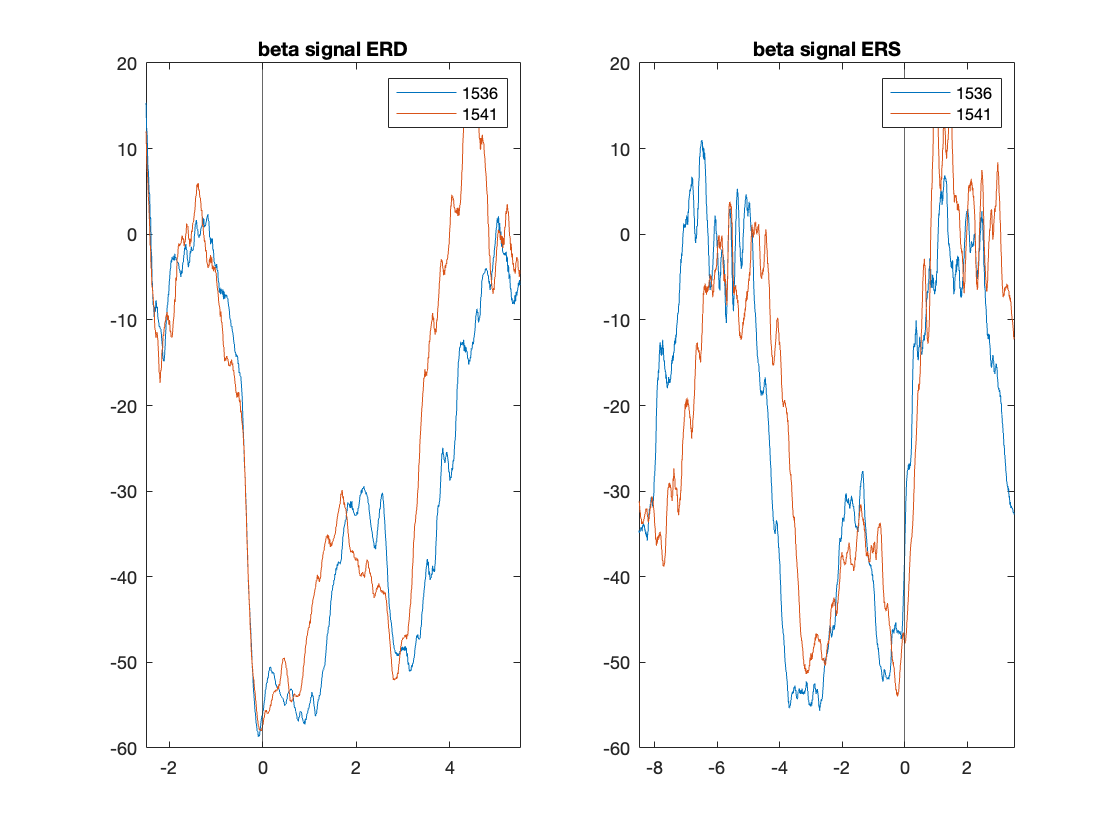



figure();
subplot(1,2,1)
plot(t,grand_mean_beta_1536(43,:))
hold on 
plot(t,grand_mean_beta_1541(43,:))
xline(0);xlim([-2.5 5.5]);legend('1536','1541');title('beta signal ERD')

subplot(1,2,2)
plot(t_ERP,grand_mean_beta_ERP_1536(43,:))
hold on 
plot(t_ERP,grand_mean_beta_ERP_1541(43,:))
xline(0);xlim([-8.5 3.5]);legend('1536','1541');title('beta signal ERS')

%set(G2,'Position',[10 10 2000 750]);


% figure
% plot(t,grand_mean_beta_1536(28,:))
% hold on 
% plot(t,grand_mean_beta_1541(28,:))
% xline(0);xlim([-2.5 5.5]);
% legend('1536','1541')
% figure
% plot(t,grand_mean_beta_1536(28,:))
% hold on 
% plot(t,grand_mean_mu_1536(28,:))
% xline(0);xlim([-2.5 5.5]);
% legend('beta','mu')

eeglab;close;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


waitfor(msgbox("Now, please select your loc file without EOG channels", 'Loc file selection'));
[locs_noica,locpath_noica]=uigetfile('*.loc', 'Pick a channel location file');
locpath_noica=strrep(locpath_noica,'\','\\'); %for windows
locs_noica=append(locpath_noica,locs_noica);

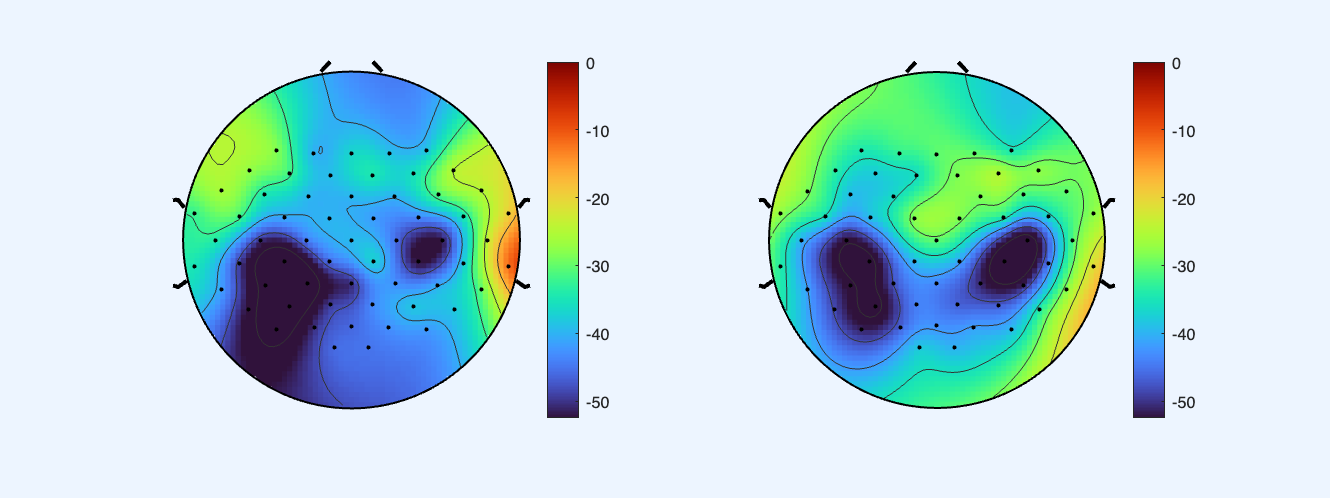

readlocs(): 'loc' format assumed from file extension


H1=figure(10);
subplot(1,2,1)
D7_topoplots(grand_mean_mu_1536,locs_noica);

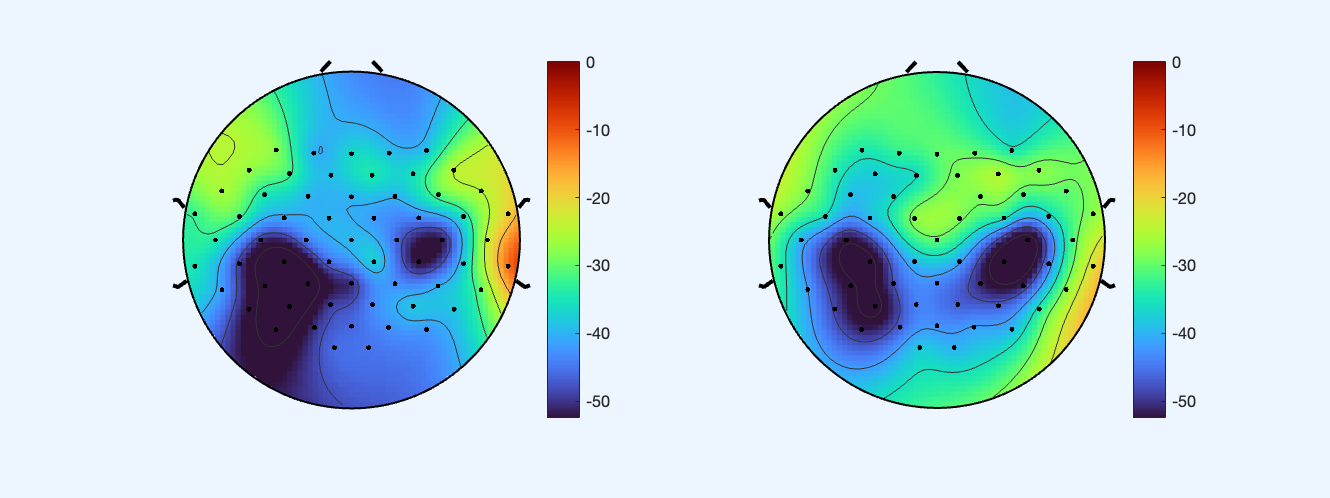

readlocs(): 'loc' format assumed from file extension


subplot(1,2,2)
D7_topoplots(grand_mean_mu_1541,locs_noica);

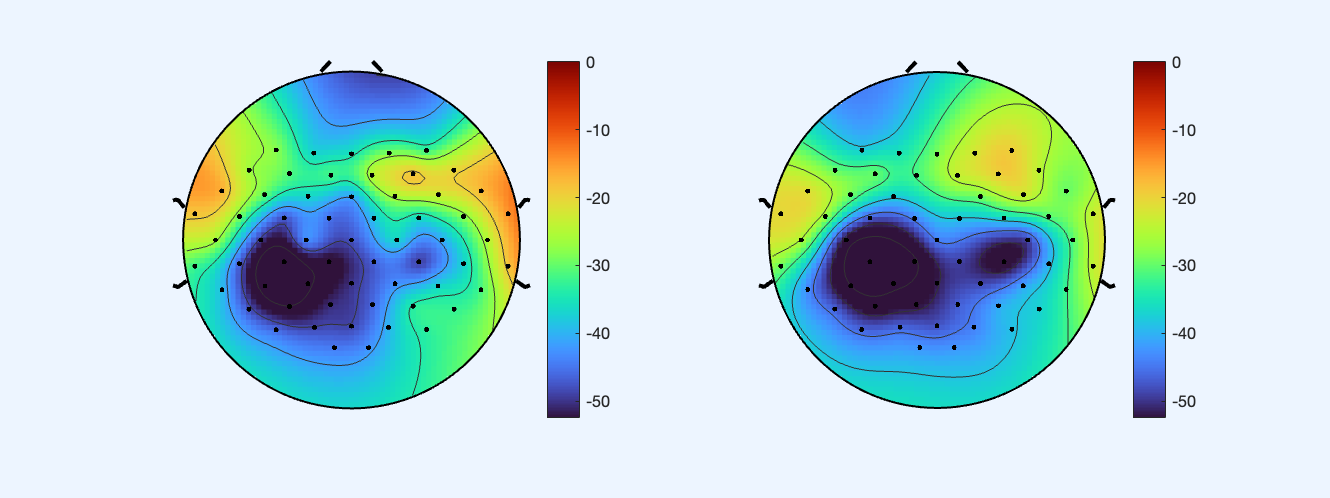

readlocs(): 'loc' format assumed from file extension


set(H1,'Position',[10 10 2000 750]);

H2=figure(11);
subplot(1,2,1)
D7_topoplots(grand_mean_beta_1536,locs_noica);

readlocs(): 'loc' format assumed from file extension


subplot(1,2,2)
D7_topoplots(grand_mean_beta_1541,locs_noica);

set(H2,'Position',[10 10 2000 750]);

a=spectrogram(grand_mean_mu_1536(43,:))

a = 1.0e+04 *

  -0.3207 + 0.0000i  -0.7078 + 0.0000i  -2.5860 + 0.0000i  -2.7936 + 0.0000i  -2.3033 + 0.0000i  -2.3410 + 0.0000i  -2.0238 + 0.0000i  -0.9779 + 0.0000i
   0.0208 + 0.2413i   0.3383 - 0.4086i   1.4511 + 0.3536i   1.3823 + 0.5086i   1.0000 + 0.5654i   1.2253 + 0.2803i   0.9156 + 0.6232i   0.3261 + 0.2996i
   0.1122 + 0.0099i   0.0876 + 0.2039i  -0.0902 - 0.1510i  -0.1012 - 0.0331i   0.0540 - 0.0494i  -0.1766 + 0.0437i  -0.0217 - 0.0870i   0.0964 + 0.0396i
   0.0849 - 0.0522i  -0.1294 + 0.0458i  -0.0393 - 0.0476i   0.0087 + 0.0003i  -0.0056 - 0.0430i   0.0619 - 0.0231i   0.0204 - 0.0301i  -0.0601 - 0.0554i
  -0.0334 - 0.0386i   0.1042 - 0.0581i  -0.0060 + 0.0189i   0.0059 + 0.0082i  -0.0194 + 0.0434i  -0.0350 + 0.0075i  -0.0084 + 0.0260i   0.0958 + 0.0448i
  -0.0001 + 0.0192i  -0.0692 + 0.0568i  -0.0374 + 0.0045i   0.0002 + 0.0061i   0.0254 + 0.0106i   0.0208 + 0.0349i   0.0062 + 0.0021i  -0.0856 - 0.0072i
  -0.0085 - 0.0255i   0.0228 - 0.0100i  -0.0024 + 0.0326i  -0.0148 

b=spectrogram(grand_mean_mu_1541(43,:))

b = 1.0e+04 *

  -0.2625 + 0.0000i  -1.0464 + 0.0000i  -2.5325 + 0.0000i  -2.4068 + 0.0000i  -1.9204 + 0.0000i  -2.1239 + 0.0000i  -0.7604 + 0.0000i   0.6168 + 0.0000i
  -0.0487 + 0.2247i   0.6647 - 0.3508i   1.3631 + 0.3669i   1.1429 + 0.6181i   0.8594 + 0.2933i   1.1108 + 0.4749i   0.1617 + 0.6911i  -0.5286 - 0.2222i
   0.2298 + 0.0149i  -0.1534 + 0.1588i  -0.1216 - 0.1088i  -0.0510 - 0.1538i   0.0197 + 0.0225i  -0.1125 - 0.1114i   0.1555 - 0.1841i   0.2973 + 0.1851i
   0.0111 - 0.0877i   0.0699 + 0.0477i   0.0117 - 0.0188i  -0.0086 + 0.0499i  -0.0092 - 0.0085i  -0.0104 - 0.0091i  -0.0810 + 0.0238i  -0.1488 - 0.0493i
  -0.0036 - 0.0396i  -0.0641 - 0.0811i  -0.0805 + 0.0221i   0.0013 - 0.0140i  -0.0098 + 0.0237i   0.0052 + 0.0276i   0.0847 - 0.0028i   0.1066 + 0.0107i
  -0.0213 + 0.0261i   0.0240 + 0.0593i   0.0632 + 0.0622i   0.0013 + 0.0423i  -0.0116 + 0.0084i   0.0018 + 0.0169i  -0.0725 - 0.0086i  -0.0701 - 0.0001i
   0.0035 + 0.0009i  -0.0073 - 0.0036i  -0.0255 - 0.0333i  -0.0061 

c=a-b

c = 1.0e+04 *

  -0.0583 + 0.0000i   0.3386 + 0.0000i  -0.0535 + 0.0000i  -0.3868 + 0.0000i  -0.3829 + 0.0000i  -0.2171 + 0.0000i  -1.2634 + 0.0000i  -1.5947 + 0.0000i
   0.0695 + 0.0166i  -0.3263 - 0.0578i   0.0880 - 0.0133i   0.2395 - 0.1095i   0.1407 + 0.2721i   0.1145 - 0.1947i   0.7539 - 0.0679i   0.8547 + 0.5218i
  -0.1177 - 0.0050i   0.2411 + 0.0451i   0.0314 - 0.0422i  -0.0502 + 0.1206i   0.0343 - 0.0720i  -0.0641 + 0.1551i  -0.1772 + 0.0970i  -0.2008 - 0.1455i
   0.0737 + 0.0355i  -0.1993 - 0.0018i  -0.0510 - 0.0288i   0.0173 - 0.0496i   0.0036 - 0.0345i   0.0723 - 0.0140i   0.1014 - 0.0539i   0.0887 - 0.0061i
  -0.0298 + 0.0010i   0.1683 + 0.0231i   0.0745 - 0.0032i   0.0046 + 0.0222i  -0.0096 + 0.0197i  -0.0402 - 0.0200i  -0.0931 + 0.0288i  -0.0108 + 0.0341i
   0.0212 - 0.0068i  -0.0932 - 0.0025i  -0.1005 - 0.0576i  -0.0011 - 0.0361i   0.0371 + 0.0023i   0.0190 + 0.0180i   0.0788 + 0.0107i  -0.0155 - 0.0071i
  -0.0120 - 0.0264i   0.0301 - 0.0064i   0.0230 + 0.0659i  -0.0087 

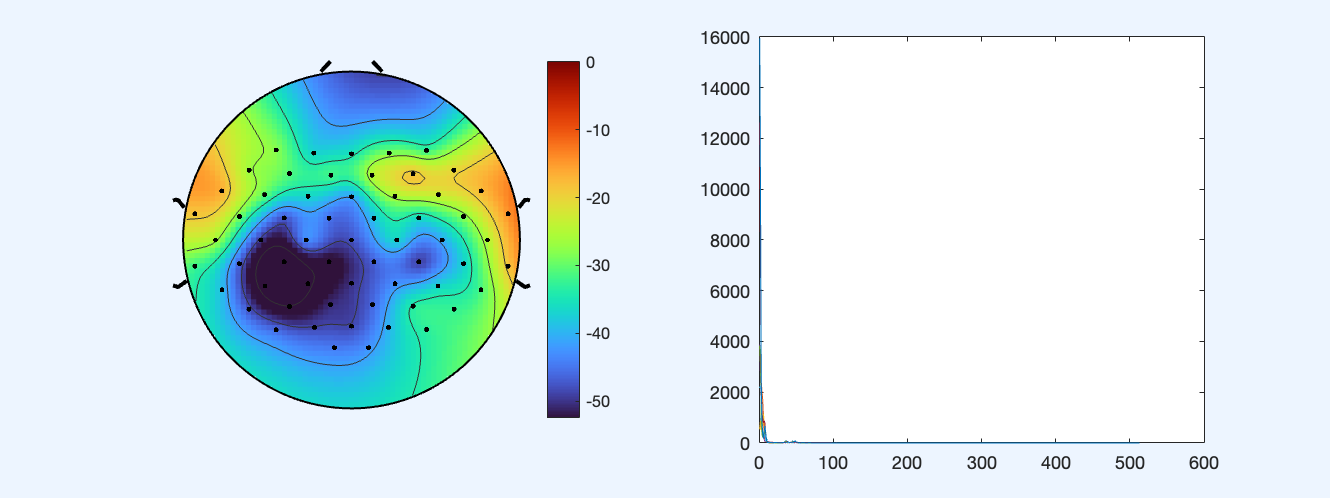

plot(abs(c))